# Integrating legacy code

Legacy code refers to existing C (or C++) functions, such as device drivers, lookup tables and general functions and interfaces. The Legacy Code Tool allows you to integrate legacy code into Simulink models. The following diagram illustrates a general procedure for using the Legacy Code Tool:

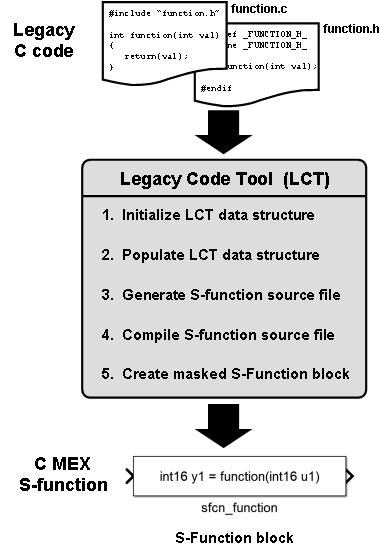

## Wrapping the legacy code

The Legacy Code Tool can integrate four function specifications into your Simulink block (of which you must specify at least one):

- **InitializeConditionsFcnSpec**: A nonempty string specifying a reentrant function that the S-function calls to initialize and reset states.

- **OutputFcnSpec**: A nonempty string specifying the function that the S-function calls at each time step. 

- **StartFcnSpec**: A string specifying the function that the S-function calls when it begins execution. This function can access S-function parameter arguments only. 

- **TerminateFcnSpec**: A string specifying the function that the S-function calls when it terminates execution. This function can access S-function parameter arguments only. 

For example the IMU driver uses the InitializeConditionsFcnSpec to open a serial connection with the IMU board. The OutputFcnSpec is used to call an update function which retrieves the latest IMU data. Finally the TerminateFcnSpec closes the serial connection to the IMU.

While the C code for interfacing with the IMU could be compiled and run on a PC, the initialization procedure would instantly result in an error as there is no IMU to connect to. To this end the legacy code is wrapped by placing it inside a MATLAB check as below:

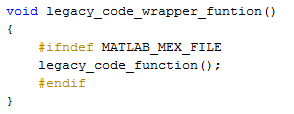

This means the "legacy_code_function" will only be executed if the compilation target is not MATLAB thus the IMU block will do nothing when simulated on the PC. Wrapping Legacy Code in these MATLAB target checks can be done in two manners:

- Call the unmodified legacy code from a new wrapper source file (as is done for the IMU_Navdata.c file via IMU_Navdata_wrapper.c).

- Modify the original Legacy Code C file such that the target check surrounds the desired code (which is how video.c is implemented).

## Generating S functions from legacy code

S functions which can be used in Simulink simulations are created using the Legacy Code Tool by calling:

specs = legacy_code('initialize') 

This gives you a Legacy Code Tool data structure which allows you to specify the options for the Legacy Code Tool. In specs you must then specify the SFunctionName, desired FcnSpecs (as explained above), source files and paths and code language. The first step is to specify the specs such that an S function can be generated, which is the code that drivers a Simulink block. For the example of the IMU block this looks as below:

IMU_Block_def = legacy_code('initialize');
IMU_Block_def.SFunctionName = 'IMU_Sfcn_mex';
IMU_Block_def.InitializeConditionsFcnSpec  = 'void MDL_IMU_start()';
IMU_Block_def.TerminateFcnSpec             = 'void MDL_IMU_term()';
IMU_Block_def.OutputFcnSpec                = 'void MDL_IMU_step(IMU_Packets y1[1], int32 y2[1])';  
IMU_Block_def.SourceFiles                  = {'IMU_Navdata_Wrapper.c'};
IMU_Block_def.IncPaths                     = {''};
IMU_Block_def.Options.useTlcWithAccel      = false;
IMU_Block_def.Options.language =  'C';
IMU_Block_def.SampleTime    = 'parameterized';

In this definition there are a few things to note:

- y1 And y2 are the pointers to the IMU navdata packet and checksum flag which will form the two outputs of the IMU Simulink block. 

- The only piece of C code that is referenced is the wrapper file. As at first the definition is created to generate an S function for use in a Simulink block, which does not yet need to be compiled into target specific code the IMU_Navdata.c source is not yet needed as all calls to it are wrapped inside MATLAB target checks.

- The 'useTlcWithAccel' option which speeds up execution by in lining code is set to 'false' as recommended for driver blocks by the Legacy Code Tool documentation. 

- The sample time is set as parameterized meaning the user can specify the sample time.

The Legacy Code Tool can then be called again using this specification to actually generate the S function:

legacy_code('generate_for_sim', IMU_Block_def);

This command combines two Legacy Code Tool commands:

legacy_code('sfcn_cmex_generate',specs);
legacy_code('compile',specs);

Meaning first the S function is generated and then compiled at which point it can be used in a Simulink block. If you want to automatically generate this Simulink block you can do so via:

legacy_code('slblock_generate', specs);

In this case this is not done because the block is already present in the AR Drone 2 library and just the S functions will be compiled when a user opens the project for the first time.

## Setting up the S function for code generation

Now that we have an S function in Simulink which uses legacy code it is necessary to set it up for compilation to the target, in this case the AR Drone 2.0. However once the steps are followed to enable an S function for code generation it can be compiled to run on any target hardware. 

First the source files that are necessary for execution on the hardware must be added to the Legacy Code specification, in the example of the IMU block this is done via:

IMU_Block_def.SourceFiles  = {'IMU_Navdata.c','IMU_Navdata_wrapper.c'};
IMU_Block_def.HeaderFiles  = {'IMU_Navdata.h'};
IMU_Block_def.SrcPaths = {'.'};

To access the IMU the legacy code in 'IMU_Navdata' must be included for code generation. The SrcPath is defined as '.' as the script which is used for the Legacy Code Tool process is inside the same folder as the source code.

This then enables us to create the target language compiler (tlc) file which specifies how the S function will be compiled into C code. This is done using:

legacy_code('sfcn_tlc_generate', IMU_Block_def);

Finally you need to create an rtwmakecfg.m file which will link to the extra target specific source and header files which we defined earlier. This is the only file which does not receive a unique filename based on the S function name and as such if you wish to create multiple S functions in a single folder the rtwmakecfg should be created for all S functions at once. This is done using:

legacy_code('rtwmakecfg_generate', [IMU_Block_def; other_def_1; ... 
     other_def_N]);
 

At this point you are all set to create Simulink models that use legacy code and compile them to any target hardware such that your model can be executed on the AR Drone 2.0 independent of Simulink.

## Using legacy code with MATLAB function blocks.

If you wish to use legacy code inside a MATLAB function block in Simulink you will need to include the legacy code. Including legacy code for MATLAB functions can be done in the Configuration Parameters under the Simulation target pane. Here you can specify custom C code which should be inserted in the final executable. For the AR Drone Toolbox the Header file tab contains '#include "IMU_Navdata.h". This inclusion allows MATLAB function blocks to directly acces the IMU data from the IMU block in the sensor library.